G = 1 / (s * (s + 2));

K = 2;
z_lag = 0.05;
p_lag = 0.005;

D_lag = K * tf([1 z_lag], [1 p_lag]);
L = D_lag * G;

Kv = dcgain(s * L)

Kv = 10

ess_ramp = 1 / Kv

ess_ramp = 0.1000

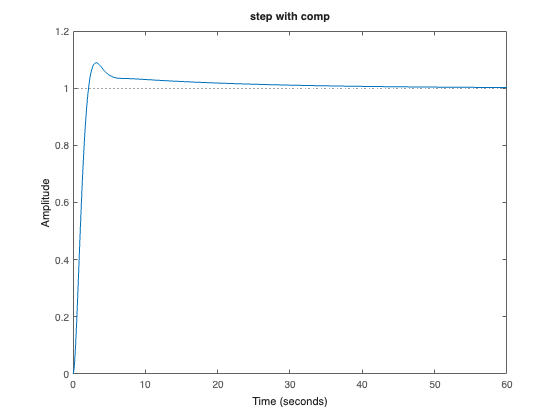


T = feedback(L, 1);
step(T);
title('step with comp');